### Cleaning

close all
clear
clc

### Time definition 

One year will be defined in 12 days (1 day from each month). One day will contain 24 hours with step size of 30 minutes.

deltaT = 0.5;   % half an hour
Time = 0:deltaT:288;

### Irradiation power and temperature recovery

### Source: 

[JRC Photovoltaic Geographical Information System (PVGIS) - European Commission (europa.eu)](https://re.jrc.ec.europa.eu/pvg_tools/en/)

% Irradiance data of Berlin for specific day of all months
Jan = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\January.csv');
Feb = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\February.csv');
Mar = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\March.csv');
Apr = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\April.csv');
May = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\May.csv');
Jun = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\June.csv');
Jul = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\July.csv');
Aug = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\August.csv');
Sep = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\September.csv');
Oct = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\October.csv');
Nov = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\November.csv');
Dec = readmatrix('D:\Matlab exercises electric modes course\Optimization of local energy networks\Irradiance and Temp data\December.csv');

Pirr_data = [Jan(1:24,3); Feb(1:24,3); Mar(1:24,3); Apr(1:24,3); May(1:24,3); Jun(1:24,3); Jul(1:24,3); Aug(1:24,3); Sep(1:24,3); Oct(1:24,3); Nov(1:24,3); Dec(1:24,3)];
Temp_data = [Jan(1:24,9); Feb(1:24,9); Mar(1:24,9); Apr(1:24,9); May(1:24,9); Jun(1:24,9); Jul(1:24,9); Aug(1:24,9); Sep(1:24,9); Oct(1:24,9); Nov(1:24,9); Dec(1:24,9)];
Time_data = 0:288;
Pirr_data(289) = Pirr_data(1);  
Temp_data(289) = 0.5*(Temp_data(288)+Temp_data(1)); 

### Interpolation and plots

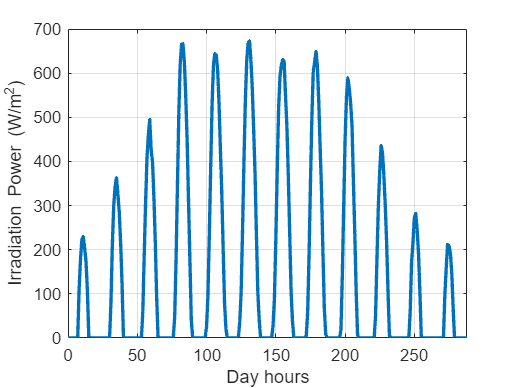

Pirr = interp1(Time_data,Pirr_data,Time);
Temp = interp1(Time_data,Temp_data,Time);
figure(1)
plot(Time,Pirr,'LineWidth',2)
axis([0 288 0 inf],'auto y')
xlabel('Day hours')
ylabel('Irradiation Power (W/m^2)')
grid

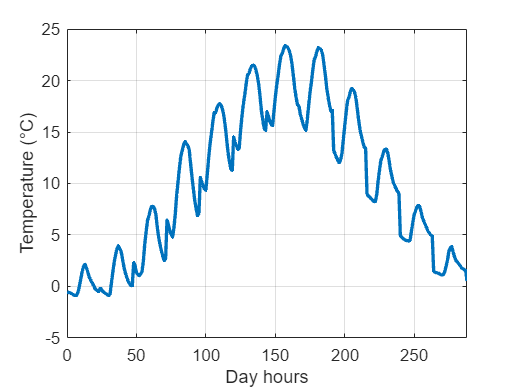

figure(2)
plot(Time,Temp,'LineWidth',2)
axis([0 288 0 inf],'auto y')
xlabel('Day hours')
ylabel('Temperature (°C)')
grid

### PV power 

% P_PV_STC: PV array rated power in standard test conditions (STC) 
% G_STC:    solar radiation under STC
% CT:       temperature coefficient
% T_STC:    temperature STC
% eta_PV:   panels efficiency (electrical)
% GSR:      global solar radiation
% T_PV:     temperature

P_PV_STC = 380; % W
G_STC = 1000;   % W/m^2
CT = -0.34e-2;  % per degree
T_STC = 25;     % celsius degrees
eta_PV = 0.95; 

GSR = Pirr;    % W/m^2
T_PV = Temp;   % celsius degrees

#### Plot of one panel produced power during a day

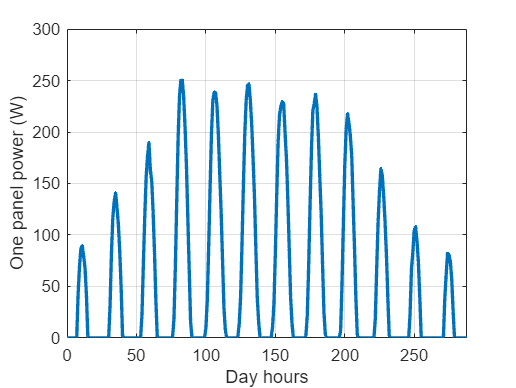

figure(3)
plot(Time,comp_P_PV(1,P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV),'LineWidth',2)
axis([0 288 0 inf],'auto y')
xlabel('Day hours')
ylabel('One panel power (W)')
grid

### Load Profile recovery and plot 

### Source: 

[Standard Load Profile Belt Load Customers 2022 (Berlin) - Data Europa EU](https://data.europa.eu/data/datasets/c9b12c46-b55a-492c-9273-6fa6eeba1631?locale=en)

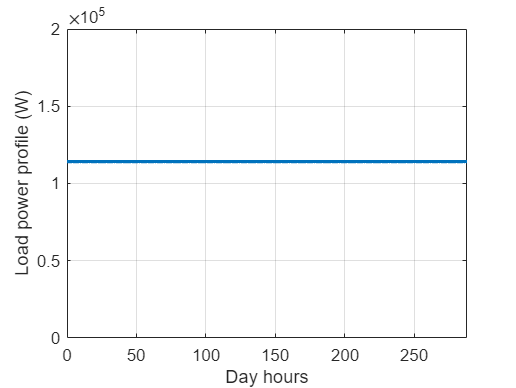

% The load corresponds to Standard Load Profile Belt Customers 2022 (Berlin) 
P_load = load('Load_Profile.txt');
figure(4)
plot(Time,P_load,'LineWidth',2)
axis([0 288 0 inf],[0 inf 0 2e5])
xlabel('Day hours')
ylabel('Load power profile (W)')
grid

### Battery, Electrolyzer and system specifications including investment costs

Source of Electrolyzer data: [Large | McPhy](https://mcphy.com/en/equipment-services/electrolyzers/large/)

C_cell = 30*3.6;  % cell capacity (W.h) 30 Ah / 3.6 V
eta_bat = 0.95;   % charging efficiency

C_el = 60;        % kW (Nomainal power required for electrolyzer)
H2_el = 0.215;    % m3/kWh (Hydrogen production capacity of electrolyzer)

eta_DCDC = 0.98;  % DC/DC converter efficiency
eta_ACDC = 0.95;  % AC DC converter efficiency

Cinv_bat = 470;   % € / kWh
Cinv_PV = 3500;   % € / kW
Cinv_el = 1500;   % € / kW

Cinv_cell = Cinv_bat*1e-3*C_cell;
Cinv_panel = Cinv_PV*1e-3*P_PV_STC;
Cinv_electrolyzer = Cinv_el*C_el;

E_load = sum(P_load)*deltaT;          % one day energy of the load
E_panel = sum(comp_P_PV(1,P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV))*deltaT;   
                    % one day energy of one single panel
Npv_min = nearest(E_load/E_panel);    % minimal number of panels

### Optimal design problem definition

**Variables :** 

- SOC_ini : intial state of battery charge

- Npv : number of PV panels

- Ncell : number of battery cells

- Nel: number of electrolyzer stacks

**Objective :**

- Cinv : total investissment cost of PV and battery

- (Optionnal) P_lost : power lost 

**Constraints :**

- Final SOC > initial SOC

- SOC min < SOC < SOC max

- Load always supplied

% X = ( Npv, Ncell, SOC_ini, )

% bounds for SOC constraints
SOC_min_bat = 0.3;
SOC_max_bat = 0.8;
Npv_max = 10000;
Ncell_min = 100;
Ncell_max = 20000;
Nel_min = 5;
Nel_max = 1000;
SOC_ini_min_bat = SOC_min_bat*1e2;
SOC_ini_max_bat = SOC_max_bat*1e2;

% lower and upper bounds constraints
Xl = [Npv_min;Ncell_min;Nel_min;SOC_ini_min_bat];
Xu = [Npv_max;Ncell_max;Nel_max;SOC_ini_max_bat];

obj = @(X) X(1)*Cinv_panel+X(2)*Cinv_cell+X(3)*Cinv_electrolyzer;  % investment cost

% no linear constraints
% non-linear constraints are defined by a specific function : "constraints"
nlconstraints = @(X) constraints(X(1),X(2),X(3),X(4)*1e-2, ...
    deltaT,P_load,eta_DCDC,eta_ACDC,eta_bat,C_cell,SOC_min_bat,SOC_max_bat, ...
    P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV);

% Options for ga (if needed):
options = optimoptions(@ga);
%options.Display = ('iter');
%options.PopulationSize = 500;
%options.MaxGenerations = 1000;
%options.FunctionTolerance = 1e-12;
%options.ConstraintTolerance = 1e-3;
[Xopt,cost] = ga(obj,3,[],[],[],[],Xl,Xu,nlconstraints,[1 2 3],options)

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Xopt = 1.0e+04 *

    0.3950    9.3766    0.0049


cost = 1.0013e+07

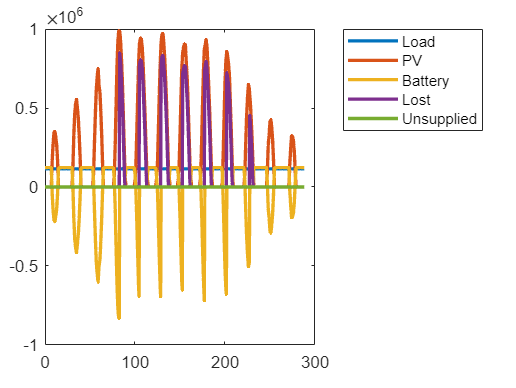


[P_pv,P_bat,SOC,P_lost,P_unsup] = comp_Power(Xopt(1),Xopt(2),Xopt(3),Xopt(4)*1e-2, ...
    deltaT,P_load,eta_DCDC,eta_ACDC,eta_bat,C_cell,SOC_min_bat,SOC_max_bat, ...
    P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV);
figure(5)
plot(Time,P_load,Time,P_pv,Time,P_bat,Time,P_lost,Time,P_unsup,LineWidth=2)
legend('Load','PV','Battery','Lost','Unsupplied','Location',"bestoutside")

## Functions definition

### PV power

function P_PV = comp_P_PV(Npv,P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV)
    % compute the power produced by Npv panel during a day

    P_PV = Npv*eta_PV*P_PV_STC/G_STC*(1+CT*(T_PV-T_STC)).*GSR;
end

### Powers computation

function [P_pv,P_bat,SOC_bat,P_lost,P_unsup] = comp_Power(Npv,Ncell,Nel,SOC_ini, ...
            deltaT,P_load,eta_DCDC,eta_ACDC,eta_bat,C_cell,SOC_min,SOC_max, ...
            P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV)
    % compute the powers in the different elements
    
    P_pv = comp_P_PV(Npv,P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV);
    n = length(P_pv);
    P_unsup = zeros(1,n);
    P_bat =  zeros(1,n);
    P_lost = zeros(1,n);
    SOC_bat = zeros(1,n+1);
    H2_el_volume = zeros(1,n);
   
    SOC_bat(1) = SOC_ini_bat;
    for k = 1:n
        if ( (eta_DCDC*P_pv(k)) >= (P_load(k))/eta_ACDC) 
            if (SOC_bat(k) < SOC_max)
                P_bat(k) = -eta_DCDC*(eta_DCDC*P_pv(k)-P_load(k)/eta_ACDC);
                SOC_bat(k+1) = min(SOC_bat(k)-eta_bat*P_bat(k)*deltaT/(Ncell*C_cell),SOC_max);
            else
                P_lost(k) = eta_DCDC*P_pv(k)-P_load(k)/eta_ACDC;
                H2_el_volume(k) = P_lost(k)*
                SOC_bat(k+1) = SOC_bat(k);
            end
        else
            if (SOC_bat(k) > SOC_min)  
                P_bat(k) = -1/eta_DCDC*(eta_DCDC*P_pv(k)-P_load(k)/eta_ACDC);
                SOC_bat(k+1) = max(SOC_bat(k)-P_bat(k)*deltaT/(Ncell*C_cell),SOC_min);
            else
                P_unsup(k) = -(eta_DCDC*P_pv(k)-P_load(k)/eta_ACDC);
                SOC_bat(k+1) = SOC_bat(k);
            end
        end
    end
end

### Optimization problem constraints

function [c,ceq] = constraints(Npv,Ncell,Nel,SOC_ini_bat, ...
        deltaT,P_load,eta_DCDC,eta_ACDC,eta_bat,C_cell,SOC_min_bat,SOC_max_bat, ...
        P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV)
    % constraints of our optimization problem
   
    [~,~,~,SOC_bat,~,P_unsup] = comp_Power(Npv,Ncell,Nel,SOC_ini_bat, ...
        deltaT,P_load,eta_DCDC,eta_ACDC,eta_bat,C_cell,SOC_min_bat,SOC_max_bat, ...
        P_PV_STC,G_STC,CT,T_STC,eta_PV,GSR,T_PV);
    
    c1 = SOC_min_bat - min(SOC_bat);
    
    c2 = max(SOC_bat) - SOC_max_bat;

    c3 = max(P_unsup);
    
    c4 = SOC_bat(1)-SOC_bat(length(SOC_bat)) ;
    
    c = [c1 c2 c3 c4];
    ceq = [];
end
